# K-NN

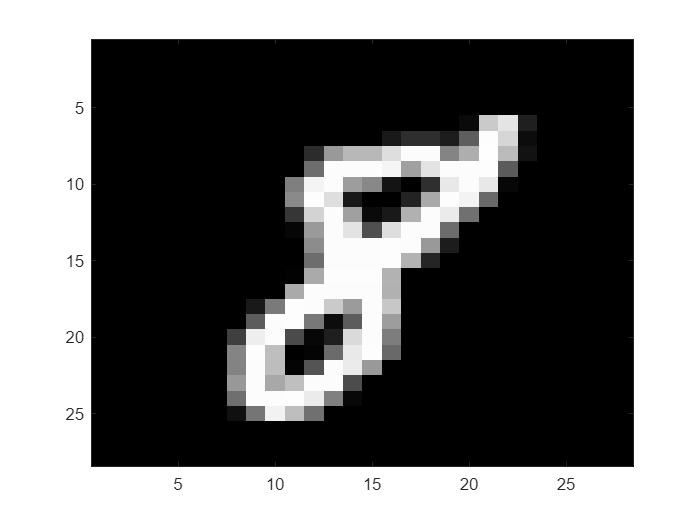

clear;clc;
load('mnist.mat');
colormap(gray);
% Sample image display
image(training.images(:,:,18)*255);

% Sample label
training.labels(18)

ans = 8

## Data Preparation

% Prepare original data matrices
X_train = zeros(training.count, training.height*training.width);
for i=1:training.count
    X_train(i,:) = reshape(training.images(:,:,i),[1,training.height*training.width]);
end
X_test = zeros(test.count, test.height*test.width);
for i=1:test.count
    X_test(i,:) = reshape(test.images(:,:,i),[1,test.height*test.width]);
end

n_test = 100; % Number of test samples to evaluate
n_dim = 50; % PCA dimensions
% Principal components
coeff = pca(X_train);
% Keeping top n_dim components
reduced_coeff = coeff(:,1:n_dim);
% Reduce dimension of both training and test data matrices
X_train = X_train*reduced_coeff;
X_test = X_test*reduced_coeff;

% Shuffle indices
idx = randperm(size(X_test,1));
% Dont shuffle indices
% idx = 1:size(X_train,1);
% Choose n_test samples for evaluation
idx = idx(1:n_test);
X_test = X_test(idx,:);

C = 10; % Number of unique labels
% Incrementing class labels by 1 as it will be used to index into matlab
% vectors and matlab has 1 indexing. Hence, label 'c' means the image
% corresponds to digit 'c-1'
Y_train = training.labels+1;
Y_test = test.labels+1;
% Choose n_test samples for evaluation
Y_test = Y_test(idx,:);

## Inference

params = [1, 3, 5, 10, 20, 30, 40, 50, 60];
stats = zeros(size(params,2),1);
for n=1:size(params,2)
    K=params(n);
    Y_pred = [];
    for i = 1:size(X_test,1)
        dists = zeros(size(X_train,1),1);
        % Find Euclidian distance of the test sample from training samples
        for j=1:size(X_train,1)
            dists(j) = norm(X_train(j,:)-X_test(i,:));
        end
        % Find the largest distance
        offset = max(dists)+1;
        % Initialize votes
        votes = zeros(C,1);
        for k=1:K
            % Find class corresponding to smallest distance
            [~, c] = min(dists);
            % Record the vote
            votes(Y_train(c)) = votes(Y_train(c)) + 1;
            % Replace the value with largest distance to find next smallest
            % distance in the next iteration
            dists(c) = offset;
        end
        % Record the class with maximum votes
        [~, c] = max(votes);
        Y_pred = [Y_pred; c];
    end
    % Record the accuracy for K
    acc = sum(Y_pred==Y_test)/size(Y_test,1);
    disp(['K:' num2str(K) ' | Accuracy:' num2str(acc)]);
    stats(n) = acc;
end

K:1 | Accuracy:0.98
K:3 | Accuracy:0.98
K:5 | Accuracy:0.96
K:10 | Accuracy:0.99
K:20 | Accuracy:0.98
K:30 | Accuracy:0.97
K:40 | Accuracy:0.97
K:50 | Accuracy:0.96
K:60 | Accuracy:0.96


## Plot

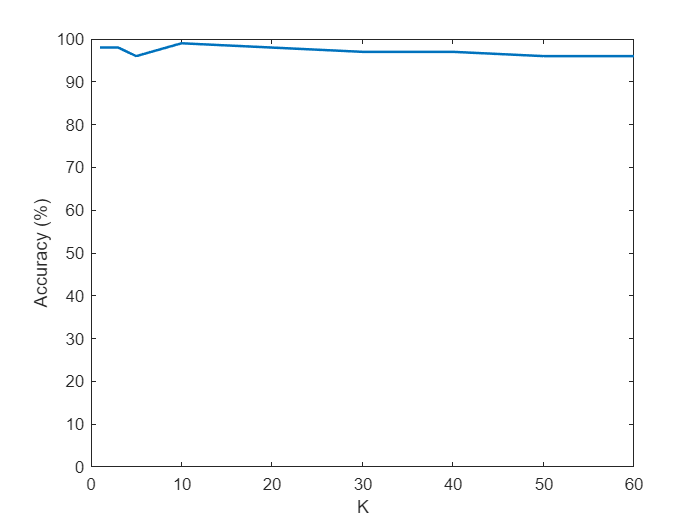

plot(params,stats*100, 'LineWidth', 1.5);
axis([0 max(params) 0 100]);
xlabel('K');
ylabel('Accuracy (%)');